Define simulation parameters

fs=600; T=1/fs;
N=60;n=0:N-1;
t=n*T;


Define signal parameters

fn = 50; % Nominal Frequency
deltaF = 0.2 % Frequency deviation

deltaF = 0.2000

f= fn+deltaF;  % Actual frequency
Udd=3; % 3V power supply voltage
Up=1; % 1V Amplitude
U0=Udd/2+0.1 % Virtual ground voltage

U0 = 1.6000

phi0 = 2*pi*rand(1)

phi0 = 3.1790

noise = 0.1*randn(1,N); % 0.1 Vrms, 


Voltage at ADC input

u=U0+Up*sin(2*pi*f*t+phi0)+ noise;
plot(u)
hold

Current plot held


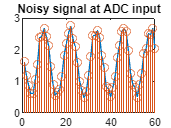

stem(u)
hold off
title("Noisy signal at ADC input")

Simulate 12 bit ADC

q = Udd/2^12 % Quantization step of 12 bit ADC

q = 7.3242e-04

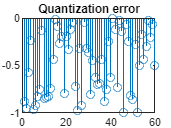

x=floor(u/q);
e=x-u/q;  % Quantization error
stem(e)
title("Quantization error")

Peak to Peak value

Xpp = max(x)-min(x)

Xpp = 3096

Upp_m = Xpp*q    % Measured peak-to-peak re-scaled to input voltage

Upp_m = 2.2676

E1=100*(Upp_m -2*Up)/(2*Up)  % Relative error in percent

E1 = 13.3789

Remove DC offset

xm=mean(x)

xm = 2.1904e+03

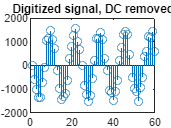

x1=x-xm;
stem(x1)
title("Digitized signal, DC removed")

Peak-to-peak average

x4=[x1(2:end) x1(1)];
stem(x1)
hold

Current plot held


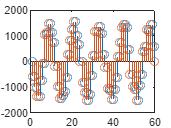

stem(x4)
hold off


Uppa = q*sum(abs(x1-x4))/(2*5)

Uppa = 2.1483



E4=100*(Uppa/2-Up)/Up  % Relative error in percent

E4 = 7.4170

Mean of rectified signal

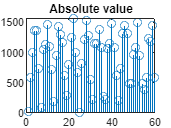

x2=abs(x1);
stem(x2)
title("Absolute value")

X2m=mean(x2)

X2m = 909.6833

U2m=X2m*q

U2m = 0.6663

U2e = Up*2/pi

U2e = 0.6366


E2=100*(U2m-U2e)/U2e  % Relative error in percent

E2 = 4.6578

Root mean square

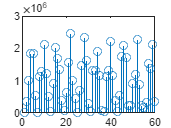

x3=x1.^2;
stem(x3)

X3m=mean(x3);
X3rms=sqrt(X3m);
U3rms_m=X3rms*q %measured rms value

U3rms_m = 0.7385

U3rms_e = Up/sqrt(2)  

U3rms_e = 0.7071


E3=100*(U3rms_m-U3rms_e)/U3rms_e  % Relative error in percent

E3 = 4.4459

Calculate Spectrum

win = hamming(N);
k=sum(win)/N;
xwin = x.*win'/k;
Nfft=8192;
Nzeros = Nfft-N;
xfft=[zeros(1,Nzeros/2) xwin zeros(1,Nzeros/2)];
X=abs(fft(xfft));
U=q*X/(N/2);
imaxe=round(1+f*Nfft/fs)

imaxe = 686

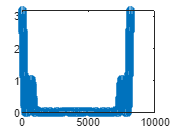

stem(U);

U50= max(U(imaxe-20:imaxe+20))

U50 = 1.0444


E5=100*(U50-Up)/Up

E5 = 4.4422